# ISET3d: Materials

PBRT scene materials are stored in this slot **thisR.materials.   **A single material can be used to describe multiple objects in the scene. 

The slot is a struct that contains a number of useful entries.  The Simple Scene contains eight different materials.

The materials are stored as a Matlab 'map', which makes them easier to search through for large, complicated scenes.  Some of our scenes use a thousand different materials.

We read and write material properties using the usual set/get method

Setting material properties is essential for making realistic scenes.  We are constantly documenting and adding guides to specify materials with understandable names and properties. There was a substantial change in material properties in PBRT V4.0 so we are not likely to run out of tasks any time soon.

A material has many properties that define the object's color, surface roughness, specularity, and opacity. The color properties are separated in diffusion reflectance (kd), specular reflectance (ks), and mirror reflectance (kr).   We can specify the color in various ways, including RGB and spectral reflectance.

This tutorial illustrates how to set/get material properties and how to create new materials.

**See also**

  t_materials.m, piMaterialCreate, t_assets, t_piIntro*

## The base scene

This is the low resolution simple scene. We will introduce a set of material changes

ieInit;
if ~piDockerExists, piDockerConfig; end
thisR = piRecipeDefault('scene name', 'SimpleScene');

Read 1 materials.
Read 1 textures.
***Scene parsed.


thisR.set('film resolution',[200 150]);
thisR.set('rays per pixel',32);
thisR.set('fov',45);
thisR.set('nbounces',5); 

piWrite(thisR);

Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt


scene = piRender(thisR, 'render type', 'radiance');

Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene":"/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/renderings/SimpleScene.dat /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt
*** Rendering time for SimpleScene:  3.3 sec ***

  Reading image h=150 x w=200 x 31 spectral planes.


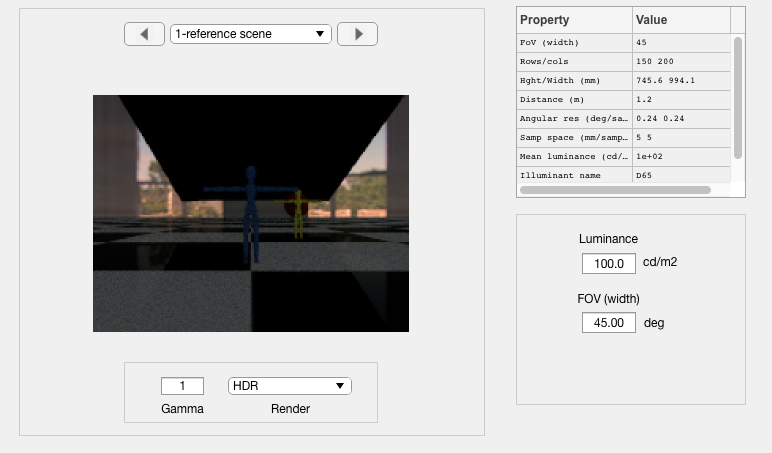

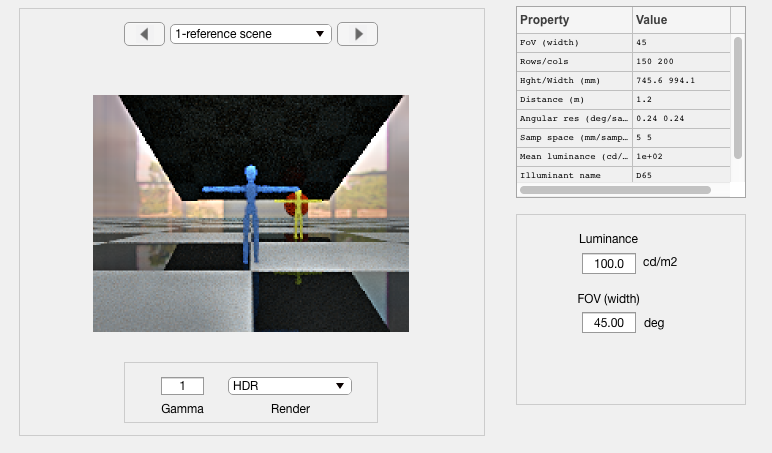

scene = sceneSet(scene, 'name', 'reference scene');
sceneWindow(scene);
sceneSet(scene, 'render flag', 'hdr');

## List the scene materials

To list the materials in the scene, use this command

thisR.get('material print');


Scene materials: SimpleScene
-------------------------------
           name       type 
         _________    _____

    1    BODY         uber 
    2    GLASS        glass
    3    Material     uber 
    4    mirror       uber 
    5    uber         uber 
    6    uber_blue    uber 

-------------------------------


## The material of an asset

Each asset (object node in the tree) has a material name.  We find the material for an object this way.

% The material of the blue stick figure
assetName = '001_figure_3m_O'; 
thisR.get('asset',assetName,'material name')

ans = 'uber_blue'

The material of the ceiling will become a mirror.  For now it is the black surface at the ceiling.

assetName = '001_mirror_O';
thisR.get('asset',assetName,'material name')

ans = 'mirror'

## Material properties

We get a material from its name.  We can also get just a specific property.

Find a material and print its properties

matName = 'uber_blue';
thisMat = thisR.get('material', matName)

thisMat = struct with fields:
              name: 'uber_blue'
      fluorescence: [1×1 struct]
     concentration: [1×1 struct]
              type: 'uber'
                kd: [1×1 struct]
                ks: [1×1 struct]
                kr: [1×1 struct]
                kt: [1×1 struct]
         roughness: [1×1 struct]
        uroughness: [1×1 struct]
        vroughness: [1×1 struct]
               eta: [1×1 struct]
           opacity: [1×1 struct]
    remaproughness: [1×1 struct]


Check roughness

roughness = thisR.get('material', matName, 'roughness')

roughness = struct with fields:
     type: 'float'
    value: 0.5000


Check diffuse property

kd = thisR.get('material', matName, 'kd')

kd = struct with fields:
     type: 'rgb'
    value: [0.0477 0.1075 0.3424]


Check specular reflection property

ks = thisR.get('material', matName, 'ks')

ks = struct with fields:
     type: 'rgb'
    value: [0.0331 0.0331 0.0331]


Check mirror reflection property

kt = thisR.get('material', matName, 'kr')

kt = struct with fields:
     type: 'rgb'
    value: [0.0331 0.0331 0.0331]


Check the diffusivity  (kd)

kdVal = thisR.get('material', matName, 'kd value')

kdVal =     0.0477    0.1075    0.3424


Check property type (spectral, rgb)

kdType = thisR.get('material', matName, 'kd type')

kdType = 'rgb'

## Set material color: RGB format

The blue guy wants to be green today.

Change diffuse reflectance to be green

Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt
Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene":"/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/renderings/SimpleScene.dat /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt
*** Rendering time for SimpleScene:  3.8 sec ***

  Reading image h=150 x w=200 x 31 spectral planes.


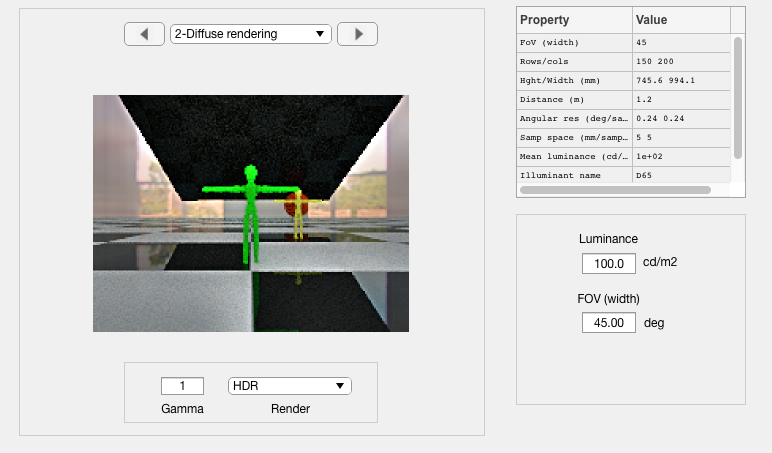

thisR.set('material', matName, 'kd value', [0 0.5 0]);
piWRS(thisR,'name','Diffuse rendering','render type','radiance');

## Set material type: glass

The blue guy is feeling like glass, now.  So make a glass material.

glass = 'blueGuyGlass';
newMat = piMaterialCreate(glass, 'type', 'glass');
thisR.set('material', 'add', newMat);

Print the blue figure material and then change it to glass.

assetName = '001_figure_3m_O';
curName = thisR.get('asset', assetName, 'material name');
disp(['The current material is',curName]);

The current material isuber_blue


Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt
Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene":"/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/renderings/SimpleScene.dat /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt
*** Rendering time for SimpleScene:  3.8 sec ***

  Reading image h=150 x w=200 x 31 spectral planes.


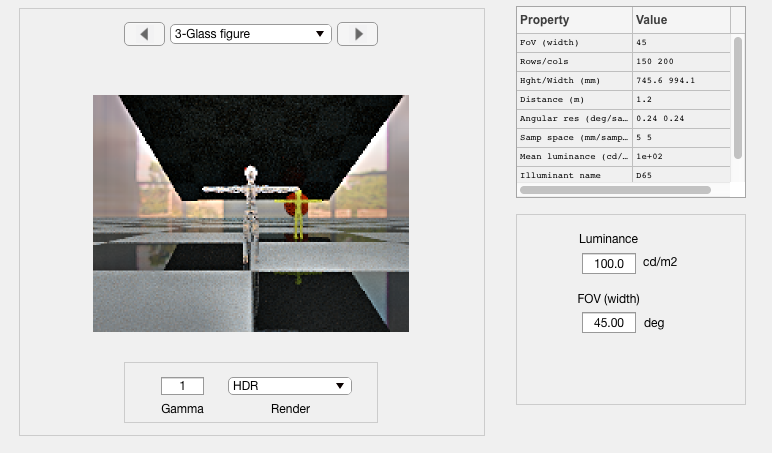

thisR.set('asset', assetName, 'material name', glass);
piWRS(thisR,'name','Glass figure','render type', 'radiance'); 

## Set material type: mirror

Create a mirror material

materialName = 'newMirror';
newMat = piMaterialCreate(materialName, 'type', 'mirror');
thisR.set('material', 'add', newMat);

This is the current black ceiling, and we change it to a mirror

Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt
Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene":"/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/renderings/SimpleScene.dat /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt
*** Rendering time for SimpleScene:  3.1 sec ***

  Reading image h=150 x w=200 x 31 spectral planes.


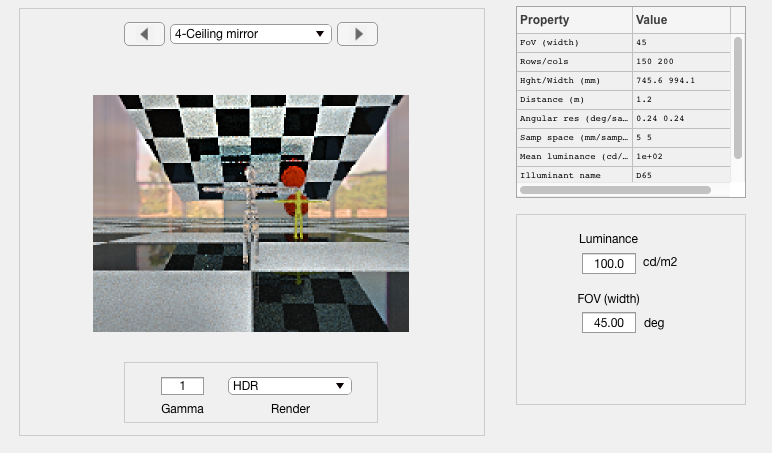

assetName = '001_mirror_O';
curName = thisR.get('asset', assetName, 'material name');
thisR.set('asset', assetName, 'material name', materialName);

piWRS(thisR,'name','Ceiling mirror','render type','radiance');

## Set material spectral reflectance

We can also specify the color using a spectral reflectance function

This is still the ceiling

assetName = '001_mirror_O';

Set the spectral reflectance of the matte material to the reflectance of the 10th chip in the MCC.  It is very red.

wave = 400:10:700;
mccRefs = ieReadSpectra('macbethChart', wave);
thisRef = mccRefs(:, 10);
ieNewGraphWin;
plotReflectance(wave,thisRef);
redName = 'newMatte';
redMaterial = piMaterialCreate(redName, 'type', 'matte');
thisR.set('material', 'add', redMaterial);

Convert the reflectance to the PBRT spd format.  It is (wave, value) ...

spdRef = piMaterialCreateSPD(wave, thisRef);

Store the spd reflectance as the diffuse reflectance of the newMatte material

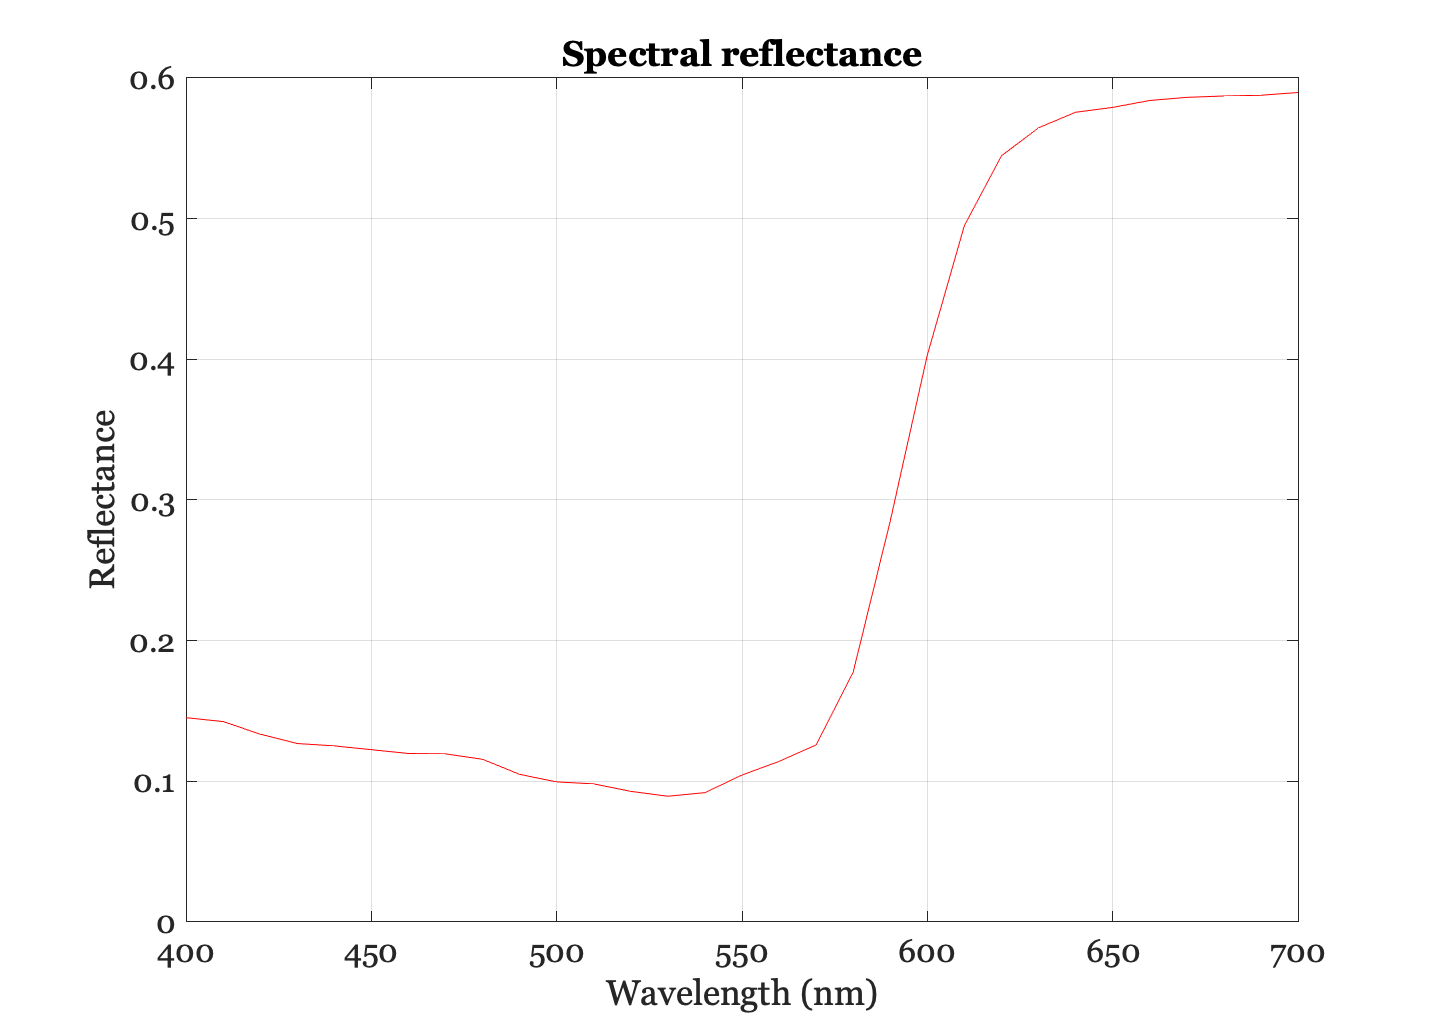

Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt
Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene":"/Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene" vistalab/pbrt-v3-spectral:latest pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/renderings/SimpleScene.dat /Users/wandell/Documents/MATLAB/iset3d/local/SimpleScene/SimpleScene.pbrt
*** Rendering time for SimpleScene:  3.8 sec ***

  Reading image h=150 x w=200 x 31 spectral planes.


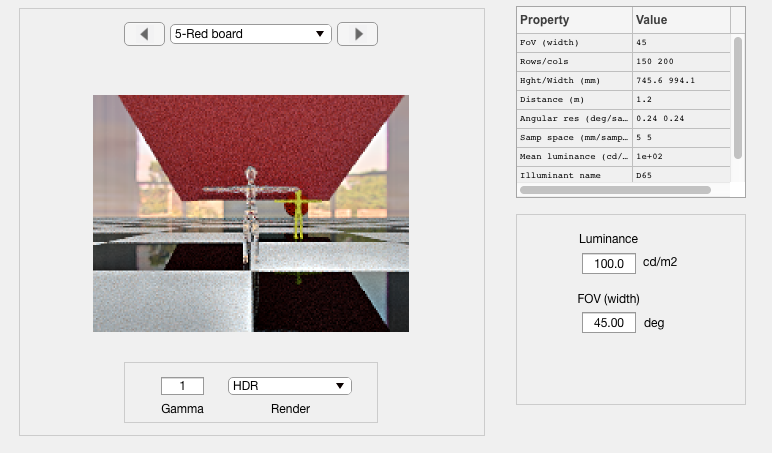

thisR.set('material', redName, 'kd value', spdRef);
thisR.set('asset', assetName, 'material name', redName);
piWRS(thisR,'name','Red board','render type','radiance');

% sceneSet(scene, 'render flag', 'hdr');

## Delete unused material

The blue guy never wants to be blue any more.

thisR.get('materials print');


Scene materials: SimpleScene
-------------------------------
             name         type 
         ____________    ______

    1    BODY            uber  
    2    GLASS           glass 
    3    Material        uber  
    4    blueGuyGlass    glass 
    5    mirror          uber  
    6    newMatte        matte 
    7    newMirror       mirror
    8    uber            uber  
    9    uber_blue       uber  

-------------------------------


Delete uber_blue material

deleteName = 'uber_blue';
thisR.set('material', 'delete', deleteName);

ans =   Map with properties:

        Count: 8
      KeyType: char
    ValueType: any


thisR.get('material print');


Scene materials: SimpleScene
-------------------------------
             name         type 
         ____________    ______

    1    BODY            uber  
    2    GLASS           glass 
    3    Material        uber  
    4    blueGuyGlass    glass 
    5    mirror          uber  
    6    newMatte        matte 
    7    newMirror       mirror
    8    uber            uber  

-------------------------------
